clear;
clc;
load FUDS_cycle.mat;

Dsn=3.9e-14;
Dsp=1e-13;

Rsn=12.5e-6;
Rsp=8e-6;

epssn=0.471;
epssp=0.297;

Ln=100e-6;
Ls=52e-6;
Lp=183e-6;

Lsum=Ln+Ls+Lp;

cs0neg=14870;
cs0pos=3900;

csmaxneg=26390;
csmaxpos=22860;

A=1;
Rohm=2e-3;
% Rohm=0.002;

F=96485.33289;

Qn=A*Ln*epssn*csmaxneg*F/3600;  %Ah
Qp=A*Lp*epssp*csmaxpos*F/3600;  %Ah

soc0n=cs0neg/csmaxneg;
soc0p=cs0pos/csmaxpos;

% I=-17.5*[ones(2000,1);zeros(300,1);-ones(2000,1);zeros(3700,1)];
I=FUDS_cycle*17.5*2;

Jn=I*Rsn/3/epssn/F/A/Ln;
Jp=-I*Rsp/3/epssp/F/A/Lp;

socn=soc0n+cumsum(I/3600/Qn);
socp=soc0p-cumsum(I/3600/Qp);

三参数抛物线近似

tic;
dcn=three_parameter(Dsn,Rsn,Jn);
dcp=three_parameter(Dsp,Rsp,Jp);

socsurfn_three=dcn/csmaxneg+socn;
socsurfp_three=dcp/csmaxpos+socp;

TPM_V=EeqLMO(socsurfp_three)-EeqC(socsurfn_three)+I*Rohm;
toc;

历时 0.012014 秒。


分数阶Pade近似

tic;
dcsep=fom(Rsp,Dsp,Jp);
dcsen=fom(Rsn,Dsn,Jn);

socsurfp_fom=dcsep/csmaxpos+socp;
socsurfn_fom=dcsen/csmaxneg+socn;

FOM_V=EeqLMO(socsurfp_fom)-EeqC(socsurfn_fom)+I*Rohm;
toc;

历时 0.042044 秒。


DRA近似

Ds=Dsn;
Rs=Rsn;

F1=256;%采样频率
T1=1/F1;%采样周期
minTlen=256;
N=2^(ceil(log2(minTlen*F1)));
f=0:N-1;
s=(2j/T1)*tan(pi*f/N);

beta=Rs*sqrt(s/Ds);
Hd=Rs/Ds*(1./(1-beta.*coth(beta)))+(3/Rs)./s;
Hd(1)=-Rs/5/Ds;
hd=real(ifft(Hd))*F1;
td=T1*(0:N-1);

hstep=T1*cumsum(hd);

Ts=1;
tdisc=0:Ts:256;
hdisc=[0 diff(interp1(td,hstep,tdisc))];

bigHankel=hankel(hdisc(2:257));
Hankel=bigHankel(1:127,1:127);
HankelUp=bigHankel(2:128,1:127);
[U,S,V]=svd(Hankel);

n=2;
Us=U(:,1:n);
Ss=S(1:n,1:n);
Vs=V(:,1:n);
ok=Us*sqrtm(Ss);
cl=sqrtm(Ss)*Vs';

Ahat=(ok\HankelUp)/cl;
Bhat=cl(1:n,1);
Chat=-ok(1,1:n);
Dhat=0;
sysDRA = ss(Ahat,Bhat,Chat,Dhat,Ts);

% [cseTilde,tk]=lsim(sysDRA,Jp);
tic;
csepTilde=DRA(Rsp,Dsp,Jp);
csenTilde=DRA(Rsn,Dsn,Jn);

socsurfp_dra=csepTilde/csmaxpos+socp;
socsurfn_dra=csenTilde/csmaxpos+socn;

DRA_V=EeqLMO(socsurfp_dra)-EeqC(socsurfn_dra)+I*Rohm;
toc;

历时 0.018659 秒。


P2D模型数据导入


load p2d_LMO_socnsurf_fuds.txt;
load p2d_LMO_socpsurf_fuds.txt;
load p2d_LMO_V_fuds.txt;

p2d_socpsurf=p2d_LMO_socpsurf_fuds(:,2);
p2d_socnsurf=p2d_LMO_socnsurf_fuds(:,2);
P2D_V=p2d_LMO_V_fuds(:,2);


xp=[0.2867 0.099828];
k1=xp(1);
k2=xp(2);
k3=1-k1-k2;

ensemblep=k1*csepTilde+k2*dcsep+k3*dcp;


xn=[0.21651,0.093326];
k1=xn(1);
k2=xn(2);
k3=1-k1-k2;

ensemblen=k1*csenTilde+k2*dcsen+k3*dcn;

socsurfp_eam=ensemblep/csmaxpos+socp;
socsurfn_eam=ensemblen/csmaxneg+socn;

KeTen=[-19.0962914789652	167.605184083354];
s=tf('s');
sysn=KeTen(1)/(KeTen(2)*s+1);

cn=lsim(sysn,I,0:length(I)-1);

KeTep=[14.5827306148203	430.007934377288];
s=tf('s');
sysp=KeTep(1)/(KeTep(2)*s+1);
tic;
cp=lsim(sysp,I,0:length(I)-1);

t_plus=0.363;
Rg=8.314;
T=298.15;
Rohm_ce=1.2e-3;
v_ce=(1+t_plus)*2*Rg*T/F*log((cp+1000)./(cn+1000));

EAM_V=EeqLMO(socsurfp_eam)-EeqC(socsurfn_eam)+I*Rohm+v_ce;

误差对比

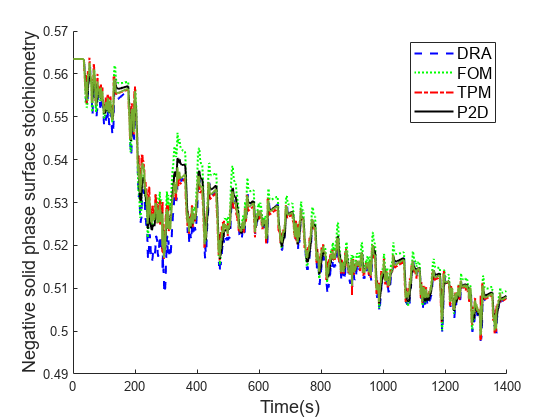

figure(1);
clf;
hold on;
plot(socsurfn_dra,'b--','LineWidth',1.5);
plot(socsurfn_fom,'g:','LineWidth',1.5);
plot(socsurfn_three,'r-.','LineWidth',1.5);
plot(p2d_socnsurf,'k','LineWidth',1.5);
plot(socsurfn_eam,"lineWidth",1.5);
xlabel('Time(s)','fontsize',14);
ylabel('Negative solid phase surface stoichiometry','fontsize',14);
legend('DRA','FOM','TPM','P2D','fontsize',12);

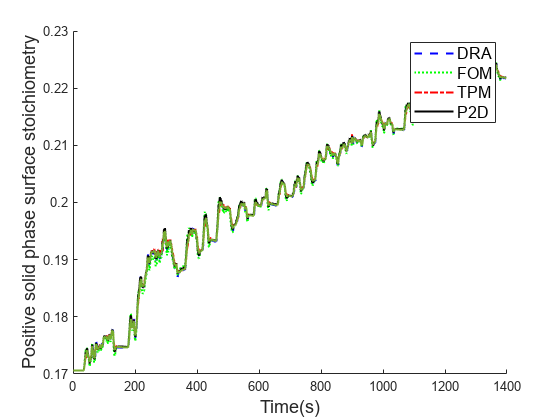

DRAn_RMSE=1000*sqrt(mean((socsurfn_dra-p2d_socnsurf).^2));
FOMn_RMSE=1000*sqrt(mean((socsurfn_fom-p2d_socnsurf).^2));
TPMn_RMSE=1000*sqrt(mean((socsurfn_three-p2d_socnsurf).^2));

DRAn_MAPE = 100*mean(abs((p2d_socnsurf - socsurfn_dra)./p2d_socnsurf));
FOMn_MAPE = 100*mean(abs((p2d_socnsurf - socsurfn_fom)./p2d_socnsurf));
TPMn_MAPE = 100*mean(abs((p2d_socnsurf - socsurfn_three)./p2d_socnsurf));
figure(2);
clf;
hold on;
plot(socsurfp_dra,'b--','LineWidth',1.5);
plot(socsurfp_fom,'g:','LineWidth',1.5);
plot(socsurfp_three,'r-.','LineWidth',1.5);
plot(p2d_socpsurf,'k','LineWidth',1.5);
plot(socsurfp_eam,'LineWidth',1.5);
xlabel('Time(s)','fontsize',14);
ylabel('Positive solid phase surface stoichiometry','fontsize',14);
legend('DRA','FOM','TPM','P2D','fontsize',12);

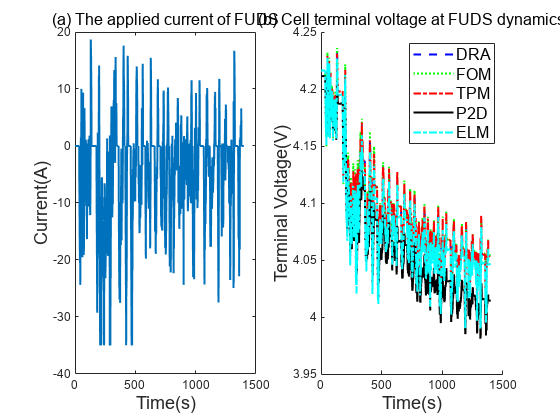

DRAp_RMSE=1000*sqrt(mean((socsurfp_dra-p2d_socpsurf).^2));
FOMp_RMSE=1000*sqrt(mean((socsurfp_fom-p2d_socpsurf).^2));
TPMp_RMSE=1000*sqrt(mean((socsurfp_three-p2d_socpsurf).^2));

DRAp_MAPE = 100*mean(abs((p2d_socpsurf - socsurfp_dra)./p2d_socpsurf));
FOMp_MAPE = 100*mean(abs((p2d_socpsurf - socsurfp_fom)./p2d_socpsurf));
TPMp_MAPE = 100*mean(abs((p2d_socpsurf - socsurfp_three)./p2d_socpsurf));
figure(3);
clf;
subplot(121);
plot(I,'LineWidth',1.5);
xlabel('Time(s)','fontsize',14);
ylabel('Current(A)','fontsize',14);
title('(a) The applied current of FUDS','FontSize',12);
subplot(122);
hold on;
plot(DRA_V,'b--','LineWidth',1.5);
plot(FOM_V,'g:','LineWidth',1.5);
plot(TPM_V,'r-.','LineWidth',1.5);
plot(P2D_V,'k','LineWidth',1.5);
plot(EAM_V,'c-.','LineWidth',1.5);
xlabel('Time(s)','fontsize',14);
ylabel('Terminal Voltage(V)','fontsize',14);
legend('DRA','FOM','TPM','P2D','ELM','fontsize',12);
title('(b) Cell terminal voltage at FUDS dynamics','FontSize',12);

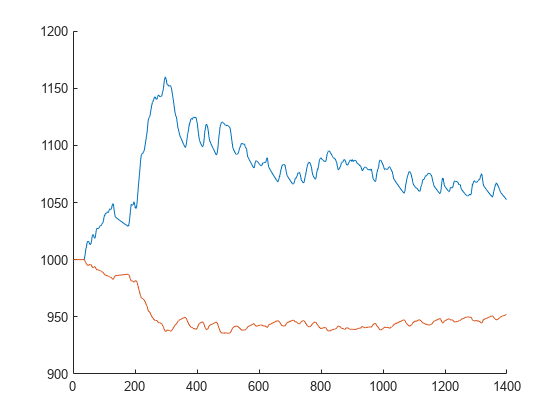

% exportgraphics(gcf,'test.png');
v_error(1,1)=1000*sqrt(mean((DRA_V-P2D_V).^2));
v_error(1,2)=1000*sqrt(mean((FOM_V-P2D_V).^2));
v_error(1,3)=1000*sqrt(mean((TPM_V-P2D_V).^2));
v_error(1,4)=1000*RMSE(EAM_V,P2D_V);


v_error(2,1) = 100*mean(abs((P2D_V - DRA_V)./P2D_V));
v_error(2,2) = 100*mean(abs((P2D_V - FOM_V)./P2D_V));
v_error(2,3) = 100*mean(abs((P2D_V - TPM_V)./P2D_V));
v_error(2,4) = 100*mean(abs((P2D_V - EAM_V)./P2D_V));

figure(4);
clf;
hold on;
plot(cn+1000);
plot(cp+1000);